### BME 3053C Final Project: Sickle Cell Detection

###  Group Members: Navya Nair, Carlos Zamario, Abilene Roberts

###  Course: BME 3053C Computer Applications for BME

###  Term: Fall 2023

###  J. Crayton Pruitt Family Department of Biomedical Engineering

###  University of Florida

###  Email: navya.nair@ufl.edu

###  December 6, 2023

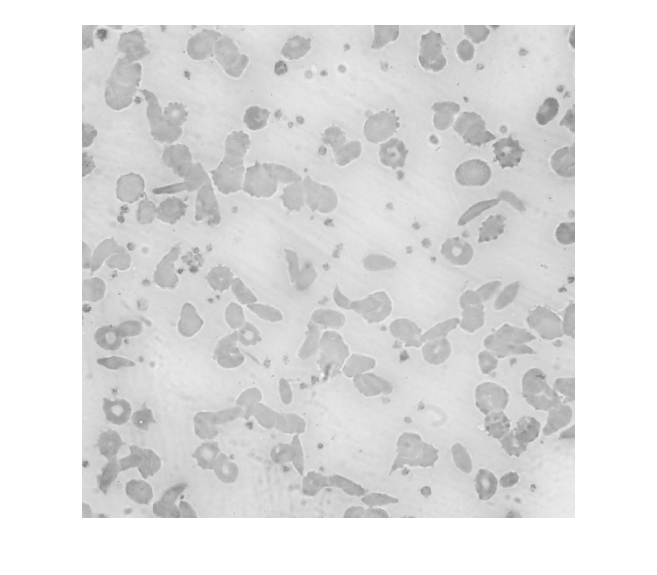

% load data, grayscale
I = imread("archive\65.jpg");
cropsize = [2000,2000];
r = centerCropWindow2d(size(I),cropsize);
I =imcrop(I,r);
%imtool(I)
%M = repmat(all(I<39,3),[1 1 2]);
%I(M) = 255;
I = rgb2gray(I);
imshow(I);


% binarize
level = graythresh(I)

level = 0.7804

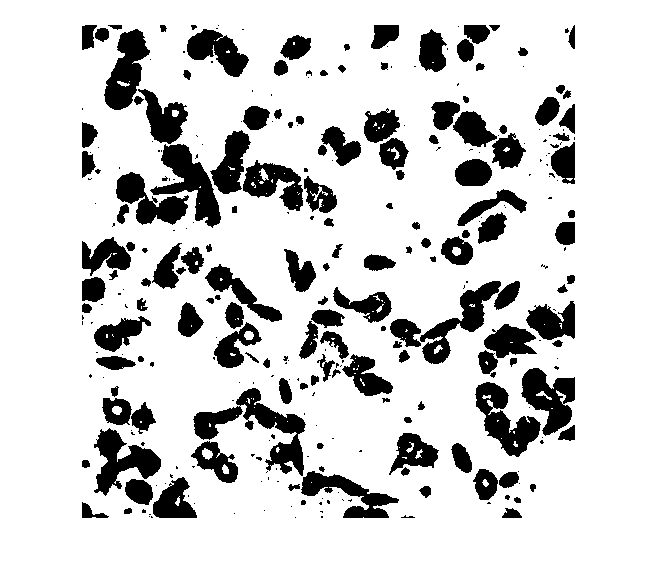

Ibinary = im2bw(I, level);
imshow(Ibinary)

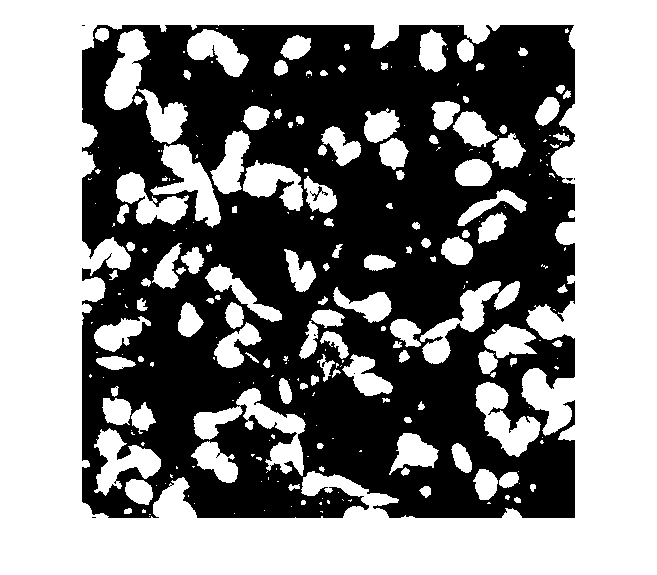

Ibinary = imfill(~Ibinary, 'holes');
imshow(Ibinary)

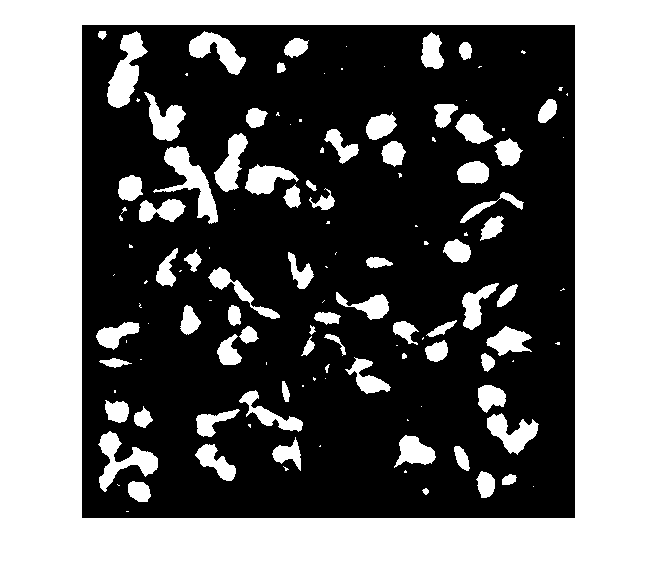

Icl = imclearborder(Ibinary);
seD = strel('diamond',10);
Ierode = imerode(Icl,seD);
imshow(Ierode)

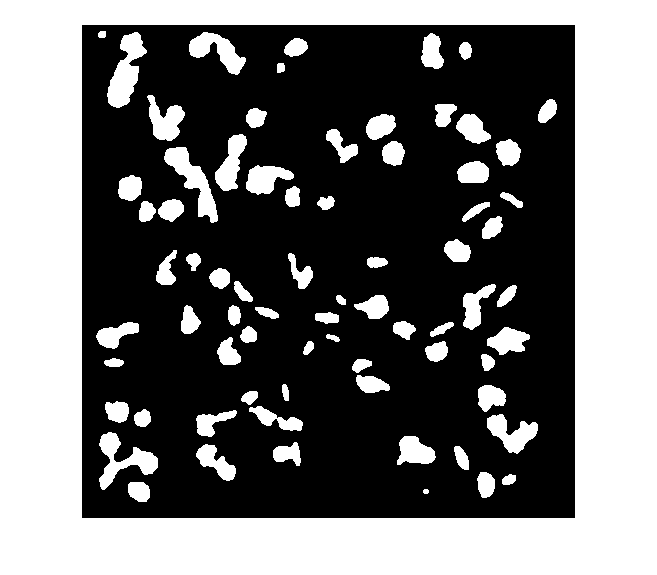

se = strel('disk', 10); % Adjust the size of the structuring element based on your image
Iopen = imopen(Ierode, se);
imshow(Iopen)

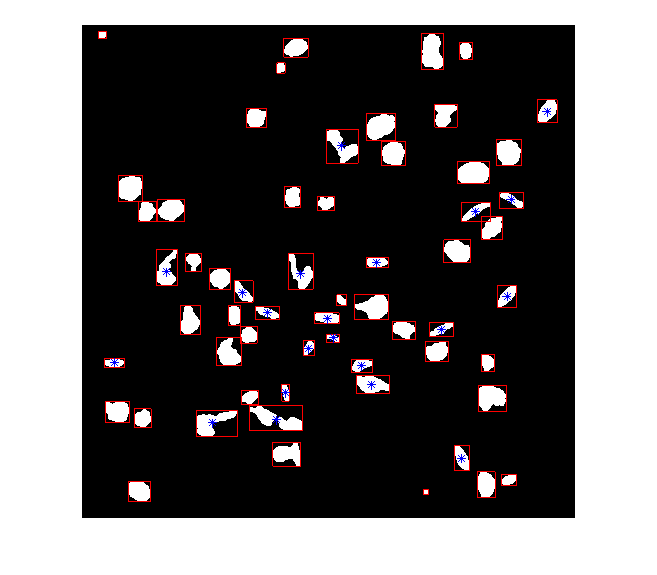

% Identify connected components in the opened image
cc = bwconncomp(Iopen);
% Ilar = bwareaopen(Iopen, 100);
% imshow(Ilar)
Irange = bwareafilt(Iopen, [100 10000]);
imshow(Irange)
[L, n] = bwlabel(Irange);
%imshow(L)
s = regionprops(L, 'Centroid','BoundingBox','MajorAxisLength','MinorAxisLength');
C = [s.Centroid];
centroidx = C(1:2:length(C));
centroidy = C(2:2:length(C));
BB= [s.BoundingBox];
xcorner = BB(1:4:length(BB));
ycorner = BB(2:4:length(BB));
xwidth = BB(3:4:length(BB));
ywidth = BB(4:4:length(BB));
mx = [s.MajorAxisLength];
mn = [s.MinorAxisLength];
sub = mx-mn;
factor = mx./sub;
rect = [xcorner ycorner xwidth ywidth];
sickle = factor<2.3;
for i= 1:1:length(xcorner)
    rectangle('Position', [xcorner(i) ycorner(i) xwidth(i) ywidth(i)], 'Edgecolor', 'r');
    if sickle(i) > 0
        hold on
        plot(centroidx(i),centroidy(i),'b*');
        hold off
    end
end

countnormal = length(xcorner) - sum(sickle);
if sum(sickle) > 0
    fprintf('The blood smear shows %d sickle cells',sum(sickle))
else
    fprintf('The blood smear is clean')
end

The blood smear shows 21 sickle cells

fprintf('There are %d normal blood cells', countnormal);

There are 38 normal blood cells